# Impulse Responses for main report

close all; clear; clc;
list_factory = fieldnames(get(groot,'factory'));
index_interpreter = find(contains(list_factory,'Interpreter'));
for i = 1:length(index_interpreter)
    default_name = strrep(list_factory{index_interpreter(i)},'factory','default');
    set(groot, default_name,'latex');
end
clear list_factory index_interpreter default_name i;

% Add paths
addpath(genpath('Responses'));

% Settings
SETTINGS.titleFS    = 18;
SETTINGS.subtitleFS = 15;
SETTINGS.labelFS    = 12;

## Load Data

load('ImpulseResponses.mat');
distances       = readmatrix('distances.txt');

colors          = zeros(6, 3);
colors(6, :)    = [1 1 1] * 0.7; % grey for noise floor
colors(1:5, :)  = distinguishable_colors(5, 'w');

dataLegends     = {'Measurement 1', 'Measurement 2', 'Measurement 3', 'Measurement 4', 'Measurement 5', 'Noise Floor'};

## Data Processing

c_air       = 343;
timestamps  = distances./c_air;

% Correcting time delay
I = zeros(5, 1);
for i = 1:5
    [~, I(i)]    = max(IR(i).Amplitude);
    IR(i).Time      = IR(i).Time - IR(i).Time(I(i)) + (7.79-1.28*2)/343;
end

clear c_air distances;

## Plot

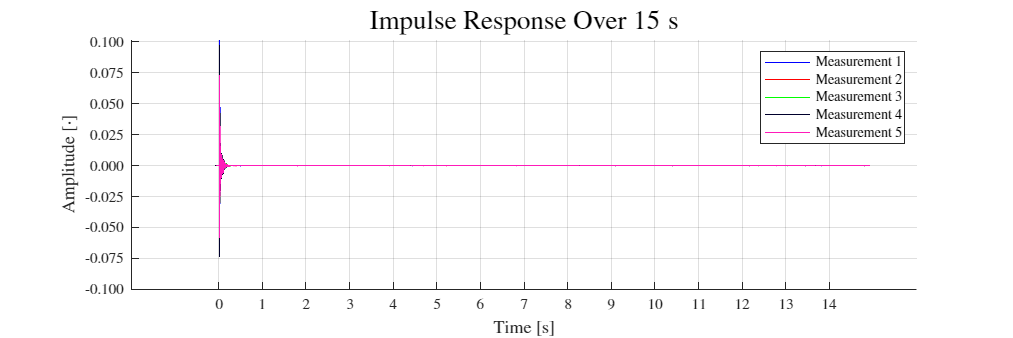

f = figure('Position', [10 10 900 300]);
hold on
for i = 1:size(IR, 1)
    s       = plot(IR(i).Time, IR(i).Amplitude);
    s.Color = colors(i, :);
end
hold off
grid on;
title('Impulse Response Over $15\; \mathrm{s}$', 'FontSize', SETTINGS.titleFS);
xticks(0:1:IR(1).Time(end));
yticks(-0.1:0.025:0.1);
%xtickformat('%.3f');
ytickformat('%.3f');
legend(dataLegends(1:5));
xlabel('Time $[\mathrm{s}]$', 'FontSize', SETTINGS.labelFS);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);


clear s i;

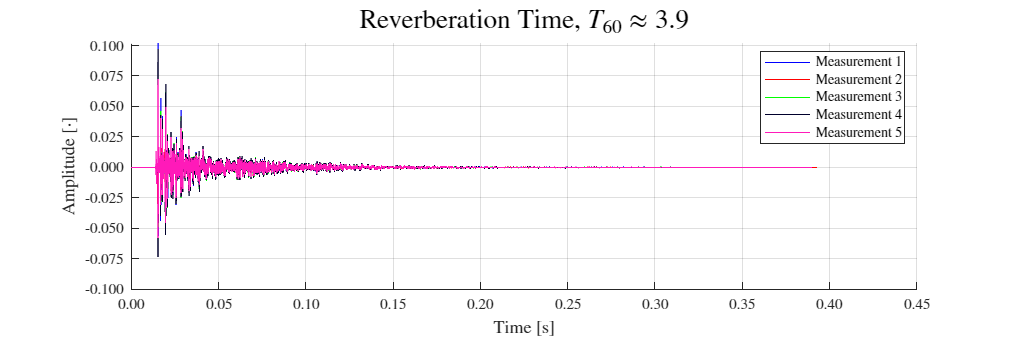

f = figure('Position', [10 10 900 300]);
hold on
for i = 1:size(IR, 1)
    signal = [IR(i).Time IR(i).Amplitude];
    signal(abs(signal(:,2)) < max(abs(signal(:, 2)))/1000, :) = [];
    s       = plot(signal(:, 1), signal(:, 2));
    s.Color = colors(i, :);
    % display(max(signal(:, 1))) % check reverberation time of each IR
end
hold off
grid on;
title('Reverberation Time, $T_{60}\approx 3.9$', 'FontSize', SETTINGS.titleFS);
xlim([0 0.45]);
yticks(-0.1:0.025:0.1);
xtickformat('%.2f');
ytickformat('%.3f');
legend(dataLegends(1:5));
xlabel('Time $[\mathrm{s}]$', 'FontSize', SETTINGS.labelFS);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);


clear s i;

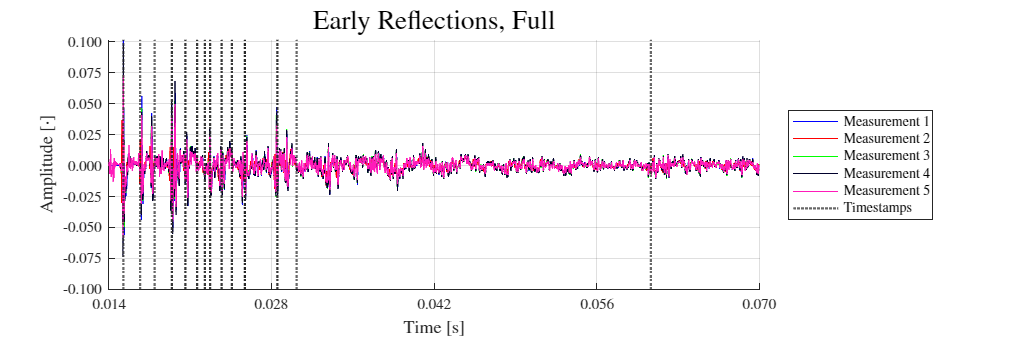

f = figure('Position', [10 10 900 300]);
hold on
for i = 1:size(IR, 1)
    signal = [IR(i).Time IR(i).Amplitude];
    signal(abs(signal(:,2)) < max(abs(signal(:, 2)))/1000, :) = [];
    s       = plot(signal(:, 1), signal(:, 2));
    s.Color = colors(i, :);
end
hold off
grid on;
title('Early Reflections, Full', 'FontSize', SETTINGS.titleFS);
xlim([0.014 0.07]);
xticks(0.014:0.014:0.07);
for i = 1:size(timestamps, 1)
    xline(timestamps(i), ':', 'LineWidth', 1.5)
end
yticks(-0.1:0.025:0.1);
xtickformat('%.3f');
ytickformat('%.3f');
legend([dataLegends(1:5), 'Timestamps'], 'Location', 'eastoutside');
xlabel('Time $[\mathrm{s}]$', 'FontSize', SETTINGS.labelFS);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);
exportgraphics(f, 'Figures\EarlyReflections_full.pdf', 'resolution', 200);

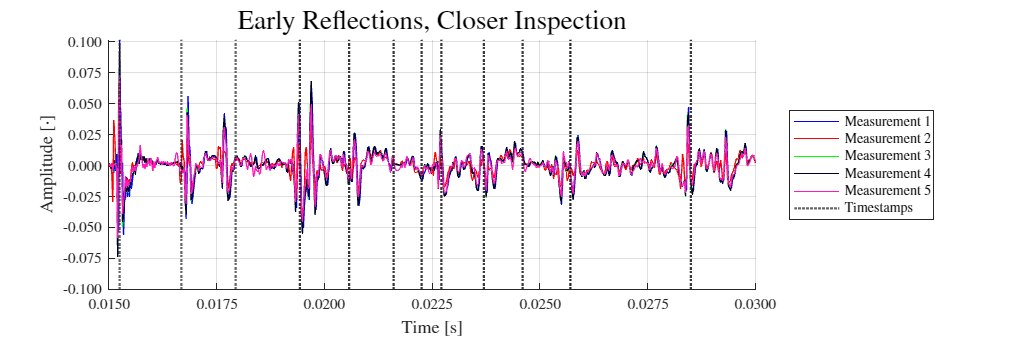

f = figure('Position', [10 10 900 300]);
hold on
for i = 1:size(IR, 1)
    signal = [IR(i).Time IR(i).Amplitude];
    signal(abs(signal(:,2)) < max(abs(signal(:, 2)))/1000, :) = [];
    s       = plot(signal(:, 1), signal(:, 2));
    s.Color = colors(i, :);
end
hold off
grid on;
title('Early Reflections, Closer Inspection', 'FontSize', SETTINGS.titleFS);
xlim([0.015 0.03]);
xticks(0.015:0.0025:0.03);
for i = 1:size(timestamps, 1)
    xline(timestamps(i), ':', 'LineWidth', 1.5)
end
yticks(-0.1:0.025:0.1);
xtickformat('%.4f');
ytickformat('%.3f');
legend([dataLegends(1:5), 'Timestamps'], 'Location', 'eastoutside');
xlabel('Time $[\mathrm{s}]$', 'FontSize', SETTINGS.labelFS);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);
exportgraphics(f, 'Figures\EarlyReflections_Close.pdf', 'resolution', 200);